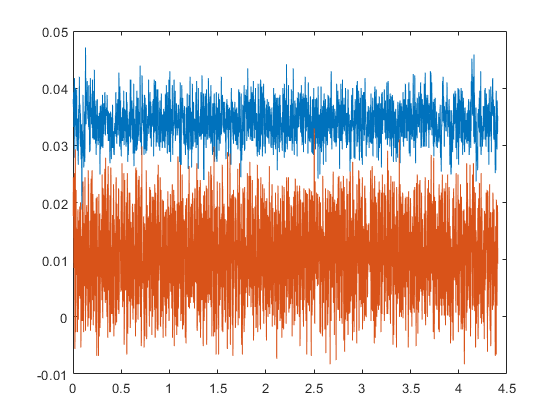

% Projekt Sensorsysteme
% Auswertung erste Messungen 

%% Daten einlesen
clc;
clear all;
close all;

g = 9.81;

file =  importdata("MessungStatisch3Achsen.TXT", ',',2);
% Split the data at $

positionSensor = file.data(:,1);
t = linspace(0.002, 0.002*length(positionSensor), length(positionSensor))'; %Zeitvektor
accelX_1 = (file.data(:,3)/2);      % Sensor unten   Due to offset (2G instead 1G we divide /2)
accelX_2 = (file.data(:,6)/2);      % Sensor oben    Due to offset (2G instead 1G we divide /2)

accelY_1 = (file.data(:,4)/2);  
accelY_2 = (file.data(:,7)/2);  

accelZ_1 = (file.data(:,5)/2);  
accelZ_2 = (file.data(:,8)/2);  

figure(1)
plot(t, accelX_1)
hold on
plot(t,accelX_2)

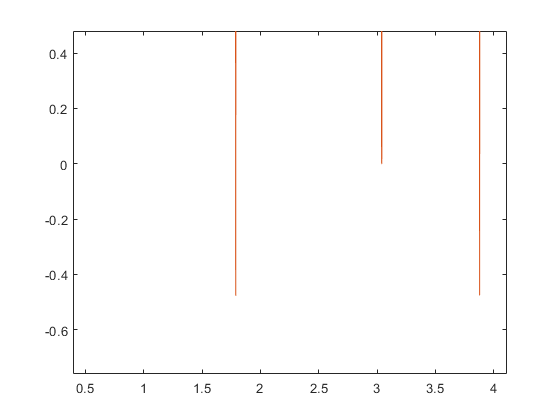


figure(2)
plot(t, accelY_1)
hold on
plot(t,accelY_2)

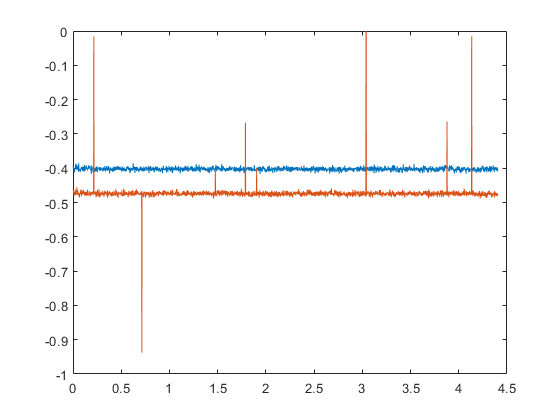


figure(3)
plot(t, accelZ_1)
hold on
plot(t,accelZ_2)